clear all;
close all;

## Load Data

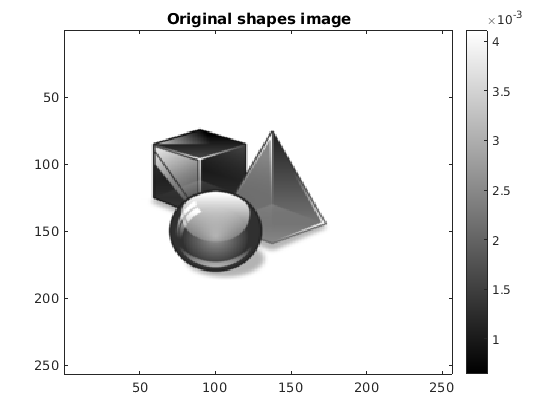

rgb = double(imread('shapes.png'));
x = mean(rgb,3);
x = double(x)/norm(x,'fro');
imagesc(x); title('Original shapes image'),colormap(gray),colorbar;

L1 = size(x,1); 
L2 = size(x,2); 
L = L1*L2;
mat = @(x) reshape(x,L1,L2);

## Blur Kernal

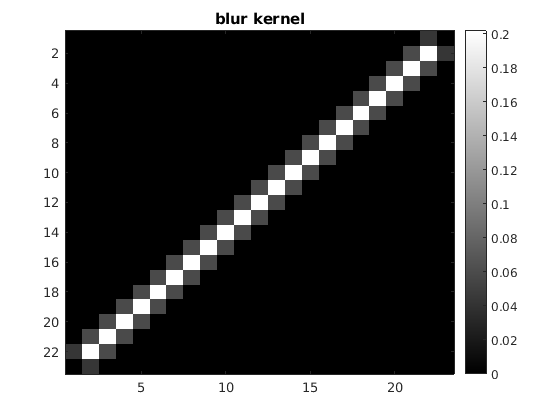

% Try different Blur Kernels
blur_kernel = fspecial('motion',30,45);
% blur_kernel = fspecial('motion',2,2);
% blur_kernel = fspecial('gaussian',[3,3],2);

[K1 K2] = size(blur_kernel); 
blur_kernel = blur_kernel/norm(blur_kernel,'fro');
w = zeros(L1,L2);

% Contribution
% K1 and K2 are odd; change if K1 and K2 even
pos_x = L1/2-K1/2+2:L1/2+K1/2;
pos_y = L2/2-K2/2+2:L2/2+K2/2;
if mod(K1,2) == 1
    pos_x = L1/2-(K1+1)/2+2:L1/2+(K1+1)/2;    
end
if mod(K2,2) == 1
   pos_y = L2/2-(K2+1)/2+2:L2/2+(K2+1)/2; 
end
w(pos_x, pos_y) = blur_kernel;
figure;
imagesc(blur_kernel),title('blur kernel'), colormap(gray), colorbar;

## 2D convolution

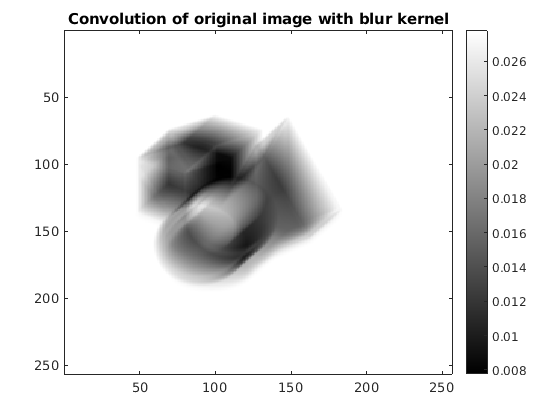

figure;
conv_wx = ifft2(fft2(x).*fft2(w));
conv_wx_image = fftshift(mat(conv_wx));
figure;
imagesc(conv_wx_image),title('Convolution of original image with blur kernel'), colormap(gray),colorbar;

## Algorithm-1 (Convex algorithm)

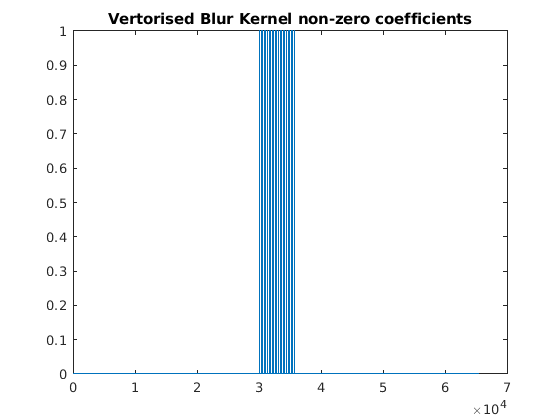

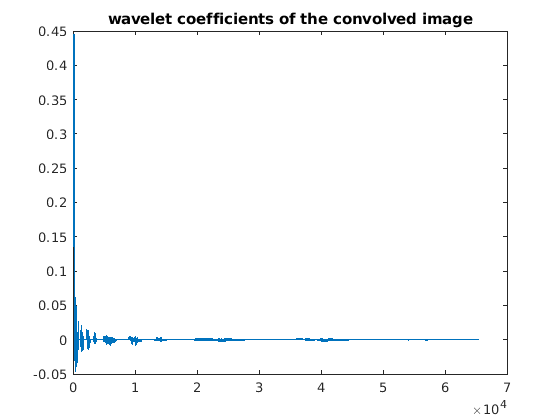

Number of non-zeros in x estimated from the blurred image: 6980
Origonal image vs Wavelet approximated image: 1.784e-02


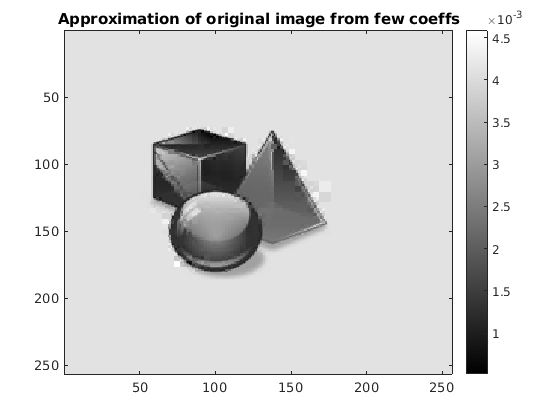

|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 1.25e-05 | 1.00e+04 |    7  |    7  |
|  2   | 7.15e-07 | 1.00e+04 |    4  |   11  |
|  3   | 5.53e-07 | 1.00e+04 |    2  |   14  |
|  4   | 2.97e-07 | 1.00e+05 |   10  |   24  |
|  5   | 2.04e-07 | 1.00e+05 |    8  |   32  |
|  6   | 1.19e-07 | 1.00e+06 |   24  |   56  |
|  7   | 9.50e-08 | 1.00e+06 |   22  |   78  |
|  8   | 6.97e-08 | 1.00e+07 |   69  |  147  |
|  9   | 5.46e-08 | 1.00e+08 |  141  |  288  |
| 10   | 5.39e-08 | 1.00e+08 |  138  |  426  |
| 11   | 4.90e-08 | 1.00e+09 |  144  |  570  |
| 12   | 4.74e-08 | 1.00e+10 |  143  |  714  |
| 13   | 3.16e-08 | 1.00e+11 |  149  |  863  |
| 14   | 1.54e-08 | 1.00e+12 |  143  |  1006  |
| 15   | 1.51e-08 | 1.00e+12 |  149  |  1155  |
| 16   | 6.31e-09 | 1.00e+13 |  151  |  1306  |
elapsed time: 1306 seconds
xEst error: 3.535e-01
h error: 6.245e-01


[xEst, wEst] = DeblurAlgorithm1(w,x, conv_wx);

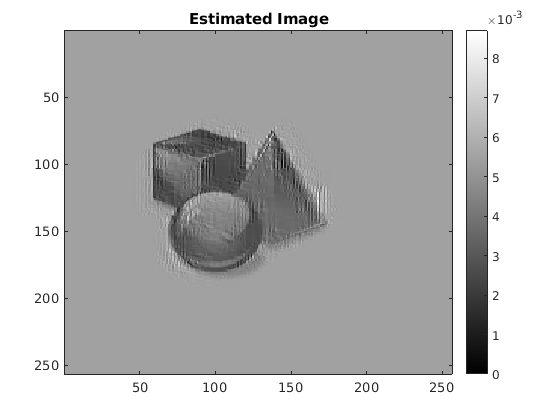

figure; 
imagesc(xEst), colormap(gray), colorbar, title('Estimated Image');

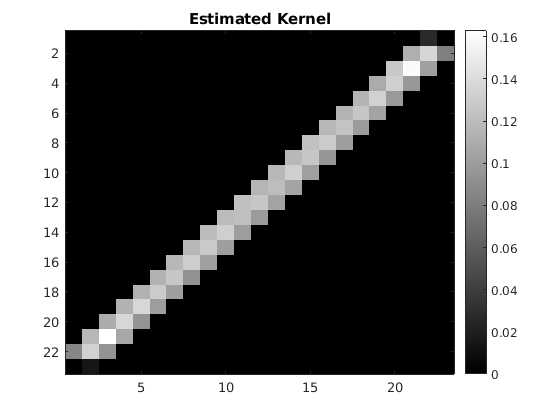

wEst = wEst(pos_x, pos_y);
figure;
imagesc(wEst),colormap(gray),colorbar, title('Estimated Kernel');

## Algorithm-2 (Prida)

[xEst, wEst] = DeblurAlgorithm2(w,x, conv_wx_image,1e-6,23,23,1500);

Working on Scale: 11 with pyramid_lambda=0.000613 and kernel size [3,3] for 1500 iterations.
Elapsed time is 1.369331 seconds.
Working on Scale: 10 with pyramid_lambda=0.000323 and kernel size [5,5] for 1500 iterations.
Elapsed time is 1.623376 seconds.
Working on Scale: 9 with pyramid_lambda=0.000170 and kernel size [7,7] for 1500 iterations.
Elapsed time is 4.805190 seconds.
Working on Scale: 8 with pyramid_lambda=0.000089 and kernel size [9,9] for 1500 iterations.
Elapsed time is 6.371654 seconds.
Working on Scale: 7 with pyramid_lambda=0.000047 and kernel size [11,11] for 1500 iterations.
Elapsed time is 12.545451 seconds.
Working on Scale: 6 with pyramid_lambda=0.000025 and kernel size [13,13] for 1500 iterations.
Elapsed time is 20.193828 seconds.
Working on Scale: 5 with pyramid_lambda=0.000013 and kernel size [15,15] for 1500 iterations.
Elapsed time is 30.358279 seconds.
Working on Scale: 4 with pyramid_lambda=0.000007 and kernel size [17,17] for 1500 iterations.
Elapsed time 

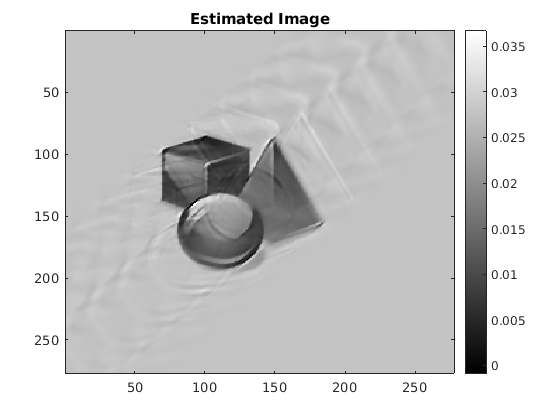

figure; 
imagesc(xEst), colormap(gray), colorbar, title('Estimated Image');

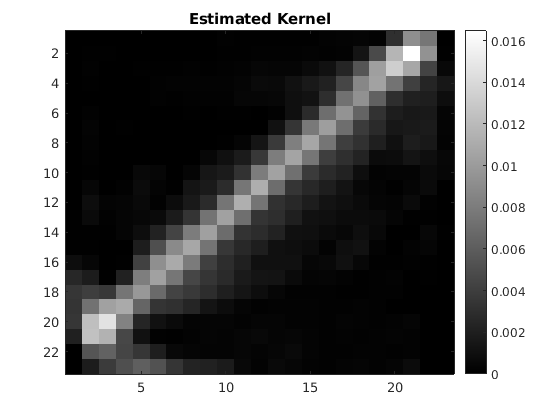

figure;
imagesc(wEst),colormap(gray),colorbar, title('Estimated Kernel');

## Algorithm-3 (Graph)

level 

4, Iter 1:1...2...3...


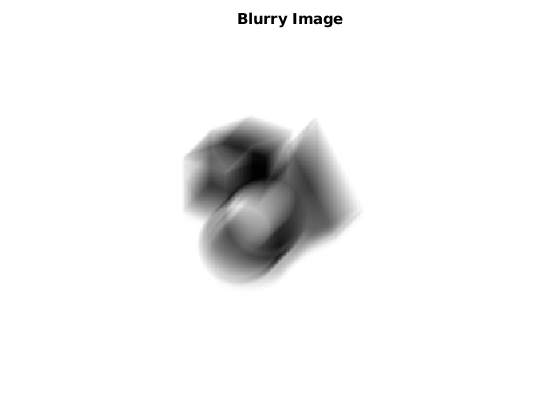

level 4, Iter 2:1...2...3...


level 4, Iter 3:1...2...3...


level 3, Iter 1:1...2...3...


level 3, Iter 2:1...2...3...


level 3, Iter 3:1...2...3...


level 2, Iter 1:1...2...3...


level 2, Iter 2:1...2...3...


level 2, Iter 3:1...2...3...


level 1, Iter 1:1...2...3...


level 1, Iter 2:1...2...3...


level 1, Iter 3:1...2...3...


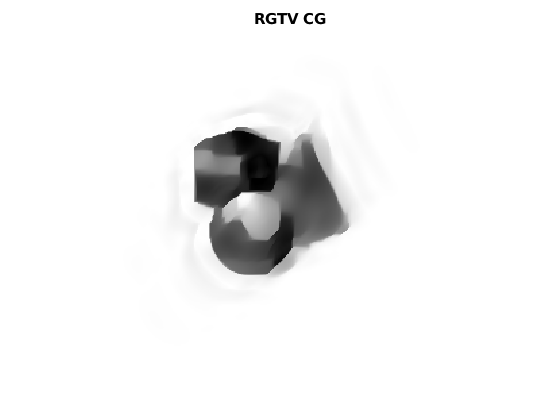

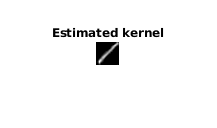

Grpah based Blind Deblurring Running Time:51.834973 s
Recomputing lookup table for new value of beta 1 and alpha 0.5
Recomputing lookup table for new value of beta 2.83 and alpha 0.5
Recomputing lookup table for new value of beta 8 and alpha 0.5
Recomputing lookup table for new value of beta 22.6 and alpha 0.5
Recomputing lookup table for new value of beta 64 and alpha 0.5
Recomputing lookup table for new value of beta 181 and alpha 0.5
FHLP Run Time: 1.962629 s


[xEst, wEst] = DeblurAlgorithm3(w,x, conv_wx_image,23);

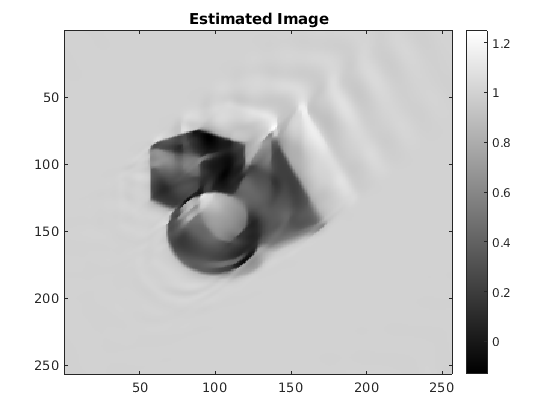

figure;
imagesc(xEst), colormap(gray), colorbar, title('Estimated Image');

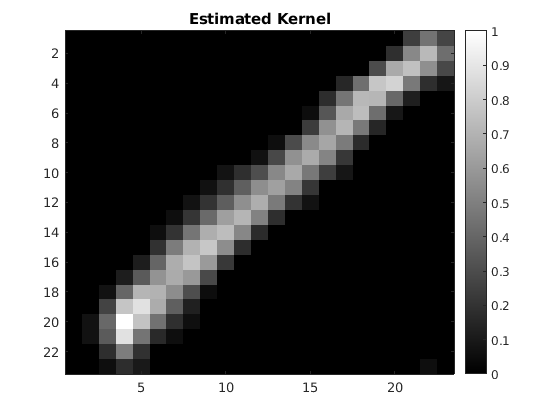

figure;
imagesc(wEst),colormap(gray),colorbar, title('Estimated Kernel');

## Load Another Data

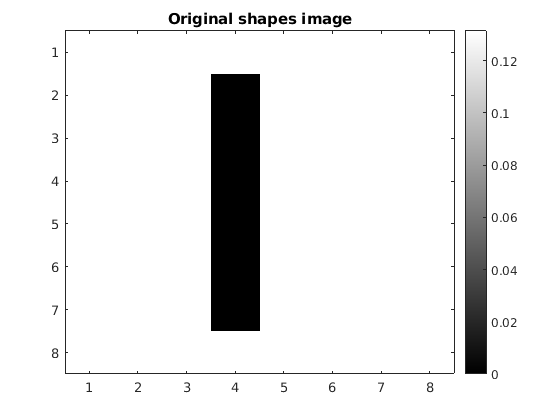

rgb = double(imread('line.png'));
x = mean(rgb,3);
x = double(x)/norm(x,'fro');
imagesc(x); title('Original shapes image'),colormap(gray),colorbar;

L1 = size(x,1); 
L2 = size(x,2); 
L = L1*L2;
mat = @(x) reshape(x,L1,L2);

## Blur Kernal

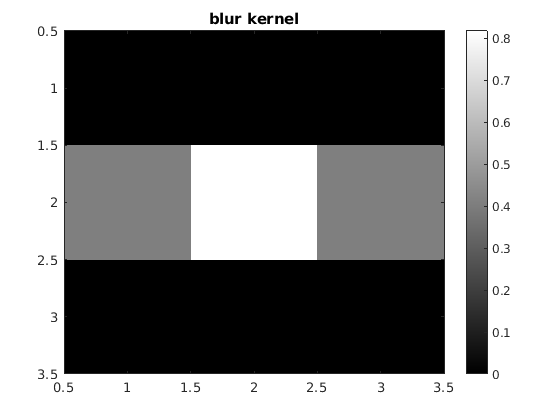

% Try different Blur Kernels
%blur_kernel = fspecial('motion',30,45);
blur_kernel = fspecial('motion',2,2);
% blur_kernel = fspecial('gaussian',[3,3],2);

[K1 K2] = size(blur_kernel); 
blur_kernel = blur_kernel/norm(blur_kernel,'fro');
w = zeros(L1,L2);

% Contribution
% K1 and K2 are odd; change if K1 and K2 even
pos_x = L1/2-K1/2+2:L1/2+K1/2;
pos_y = L2/2-K2/2+2:L2/2+K2/2;
if mod(K1,2) == 1
    pos_x = L1/2-(K1+1)/2+2:L1/2+(K1+1)/2;    
end
if mod(K2,2) == 1
   pos_y = L2/2-(K2+1)/2+2:L2/2+(K2+1)/2; 
end
w(pos_x, pos_y) = blur_kernel;
figure;
imagesc(blur_kernel),title('blur kernel'), colormap(gray), colorbar;

## 2D convolution

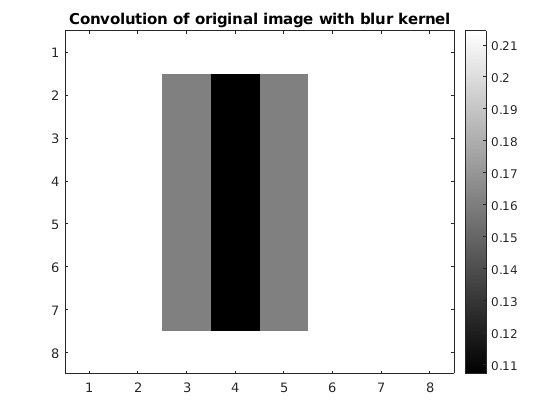

figure;
conv_wx = ifft2(fft2(x).*fft2(w));
conv_wx_image = fftshift(mat(conv_wx));
figure;
imagesc(conv_wx_image),title('Convolution of original image with blur kernel'), colormap(gray),colorbar;

## Algorithm-1 (Convex algorithm)

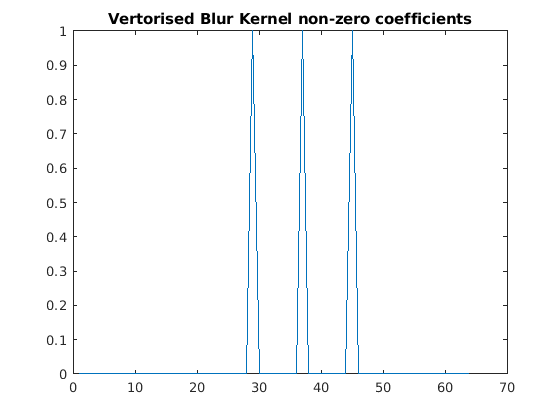

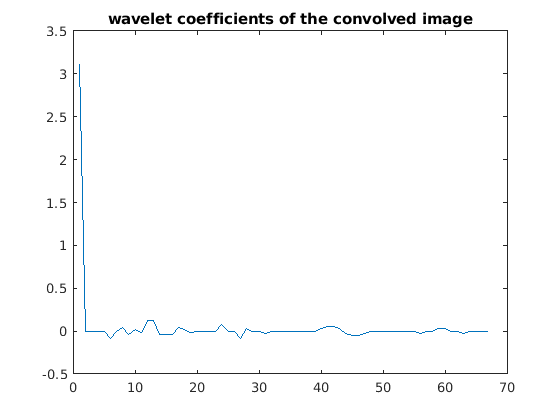

Number of non-zeros in x estimated from the blurred image: 030
Origonal image vs Wavelet approximated image: 

8.624e-16


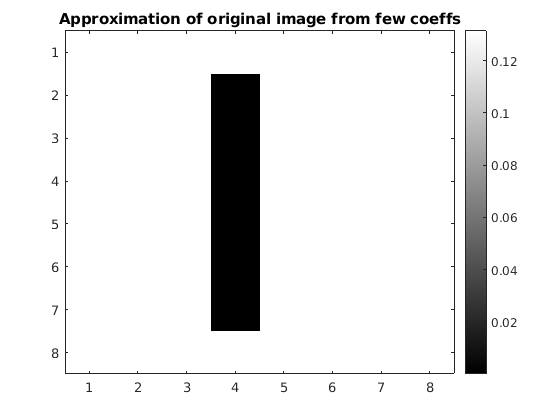

|      |          |          | iter  | tot   |
| iter |  rmse    |  sigma   | time  | time  |
----------------------------------------------
|  1   | 5.92e-04 | 1.00e+04 |    3  |    3  |
|  2   | 4.80e-04 | 1.00e+04 |    2  |    8  |
|  3   | 5.25e-05 | 1.00e+05 |    4  |   12  |
|  4   | 1.68e-05 | 1.00e+05 |    1  |   13  |
|  5   | 1.05e-05 | 1.00e+05 |    3  |   16  |
|  6   | 1.42e-06 | 1.00e+06 |    2  |   17  |
|  7   | 1.42e-06 | 1.00e+06 |    1  |   19  |
|  8   | 1.15e-07 | 1.00e+07 |    3  |   21  |
|  9   | 1.34e-07 | 1.00e+07 |    1  |   22  |
| 10   | 1.25e-08 | 1.00e+08 |    3  |   25  |
| 11   | 1.21e-08 | 1.00e+08 |    1  |   26  |
| 12   | 1.03e-09 | 1.00e+09 |    2  |   28  |
elapsed time: 29 seconds
xEst error: 4.322e-01
h error: 3.264e-01


[xEst, wEst] = DeblurAlgorithm1(w,x, conv_wx);

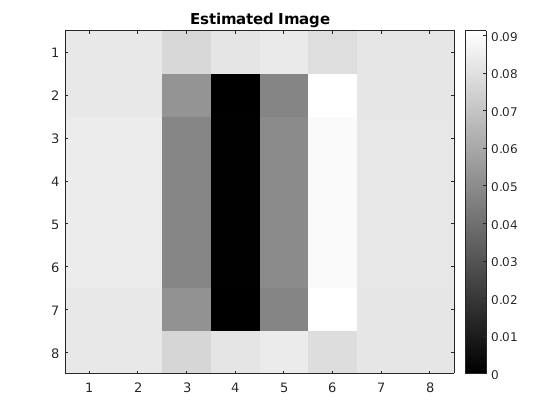

figure; 
imagesc(xEst), colormap(gray), colorbar, title('Estimated Image');

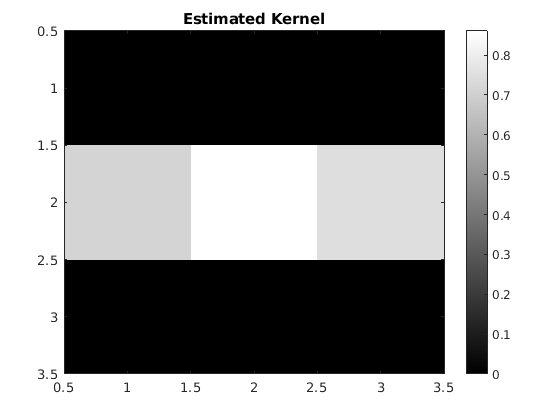

wEst = wEst(pos_x, pos_y);
figure;
imagesc(wEst),colormap(gray),colorbar, title('Estimated Kernel');

## Algorihm-2 (Robust Non-Convex algorithm)

[xEst, wEst] = DeblurAlgorithm4(w,x, conv_wx);

Number of non-zeros in x estimated from the blurred image: 032

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


error = 0.4653

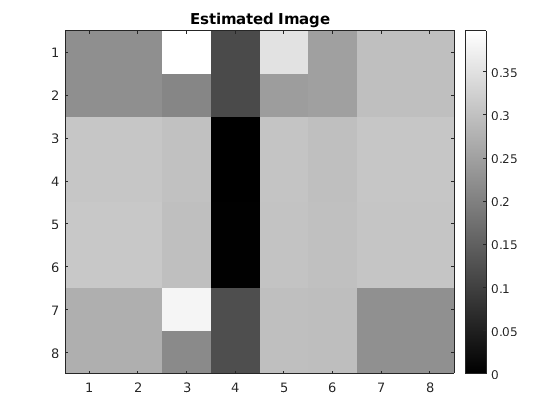

figure; 
imagesc(xEst), colormap(gray), colorbar, title('Estimated Image');

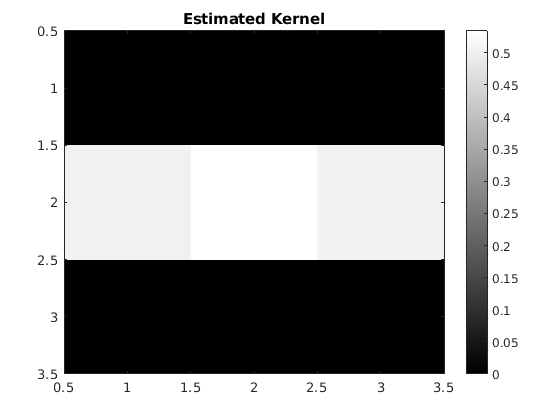

wEst = wEst(pos_x, pos_y);
figure;
imagesc(wEst),colormap(gray),colorbar, title('Estimated Kernel');